addpath(genpath('~/Downloads/dmlt/'))

load("data/datForAnal.mat")

Question 1 

Classification on timelock data

corrTrials = hpdat.trialinfo(:,3)==1;
errorTrials = hpdat.trialinfo(:,3)==0;
cfg = [];
cfg.trials = corrTrials;
corrData = ft_selectdata(cfg,hpdat);

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB


cfg.trials = errorTrials;
errorData = ft_selectdata(cfg,hpdat);

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB


% make sure there are equally many correct and error trials by creating extra copies of the error data and then removing some correct trials
% this is helpful because otherwise the classifier will pick
% up on the class imbalance to make its predictions instead
% of differences in brain activity
cfg = [];
extraErrorData = ft_appenddata(cfg,errorData,errorData,errorData,errorData);

concatenating over the "rpt" dimension


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 1 MB
the call to "ft_appenddata" took 0 seconds and required the additional allocation of an estimated 1 MB


Nerrors = length(extraErrorData.trial);
cfg.trials = 1:Nerrors;
selectedCorrData = ft_selectdata(cfg,corrData);

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB


% now run the frequency transform
cfg = [];
cfg.output = 'pow';
cfg.method = 'mtmconvol';
cfg.taper = 'hanning';
cfg.foi = 4:2:12;
cfg.t_ftimwin = ones(length(cfg.foi),1).*0.5;
cfg.channel = 'all';
cfg.toi = 0.4:0.1:0.6;
cfg.keeptrials = 'yes';
tfrcorrect = ft_freqanalysis(cfg,selectedCorrData);

the input is raw data with 115 channels and 440 trials


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
Default cfg.pad='maxperlen' can run slowly. Consider using cfg.pad='nextpow2' for more efficient FFT computation.
processing trials
trial 440, frequency 5 (12.00 Hz), 1 tapers

the call to "ft_freqanalysis" took 2 seconds and required the additional allocation of an estimated 4 MB


tfrerror = ft_freqanalysis(cfg,extraErrorData);

the input is raw data with 115 channels and 440 trials


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
Default cfg.pad='maxperlen' can run slowly. Consider using cfg.pad='nextpow2' for more efficient FFT computation.
processing trials
trial 440, frequency 5 (12.00 Hz), 1 tapers

the call to "ft_freqanalysis" took 2 seconds and required the additional allocation of an estimated 0 MB


% prepare the electrode layout
cfg = [];
cfg.elec = hpdat.elec;
lay = ft_prepare_layout(cfg,hpdat);

creating layout from cfg.elec
creating layout for ext1020 system


the call to "ft_prepare_layout" took 0 seconds and required the additional allocation of an estimated 0 MB


% cross validation
cfg = [];
cfg.layout = lay;
cfg.method = 'crossvalidate';
cfg.design = [ones(size(tfrcorrect.powspctrm,1),1);
2*ones(size(tfrerror.powspctrm,1),1)]';
cfg.statistic = {'accuracy','binomial','contingency'};
stat = ft_freqstatistics(cfg,tfrcorrect,tfrerror);

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 1 MB
using "ft_statistics_crossvalidate" for the statistical testing
fixing random number generator for reproducibility
creating sample indices using 5-fold cross-validation
validating fold 1 of 5 for 1 datasets
standardizing data
using default C=172.25
validating fold 2 of 5 for 1 datasets
standardizing data
using default C=172.25
validating fold 3 of 5 for 1 datasets
standardizing data
using default C=172.25
validating fold 4 of 5 for 1 datasets
standardizing data
using default C=172.25
validating fold 5 of 5 for 1 datasets
standardizing data
using default C=172.25


i = 1

i = 2

i = 3

i = 4

i = 5

the call to "ft_freqstatistics" took 3 seconds and required the additional allocation of an estimated 7 MB


%1b
stat.statistic.accuracy

ans = 0.8534

stat.statistic.binomial

ans = 0

%1c
stat.statistic.contingency

ans =    322   118
    11   429


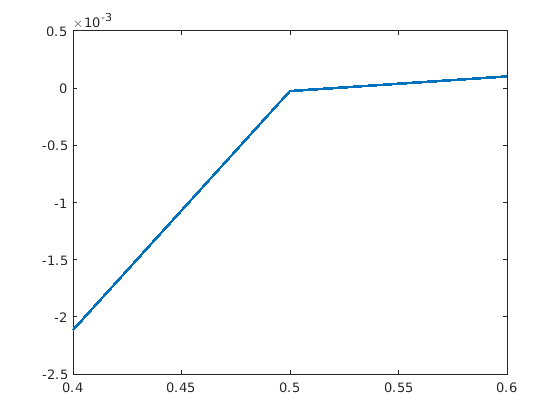

% 1d
figure(1)
plot(stat.time,squeeze(mean(mean(stat.model{1}.primal,1),2)),'LineWidth',2);

the call to "ft_prepare_layout" took 0 seconds and required the additional allocation of an estimated 1 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 2 MB
the call to "ft_topoplotER" took 1 seconds and required the additional allocation of an estimated 6 MB


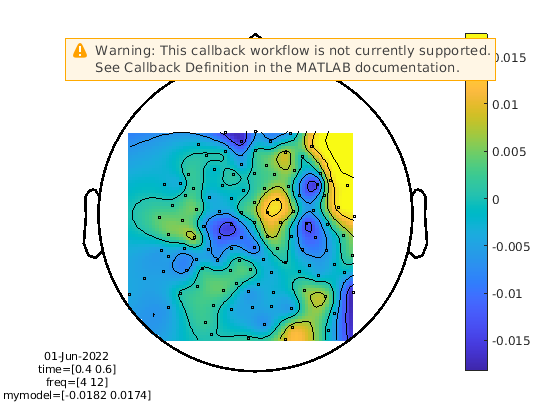

figure(2)
cfg = [];
stat.mymodel = stat.model{1}.primal;
cfg.parameter = 'mymodel';
cfg.layout = lay;
cfg.xlim = [0.4 0.6];
cfg.colorbar = 'yes';
cfg.interplimits = 'electrodes';
ft_topoplotER(cfg,stat);

Question 2

Dimensionality reduction and feature selection

cfg = [];
cfg.layout = lay;
cfg.method ='crossvalidate';
cfg.design = [ones(size(tfrcorrect.powspctrm,1),1);
2*ones(size(tfrerror.powspctrm,1),1)]';
cfg.mva = {dml.standardizer dml.enet('family','binomial','alpha',0.2)};
stat = ft_freqstatistics(cfg,tfrcorrect,tfrerror);

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
using "ft_statistics_crossvalidate" for the statistical testing
fixing random number generator for reproducibility
creating sample indices using 5-fold cross-validation
validating fold 1 of 5 for 1 datasets
validating fold 2 of 5 for 1 datasets
validating fold 3 of 5 for 1 datasets
validating fold 4 of 5 for 1 datasets
validating fold 5 of 5 for 1 datasets


i = 1

i = 2

i = 3

i = 4

i = 5

the call to "ft_freqstatistics" took 33 seconds and required the additional allocation of an estimated 1 MB


stat.statistic

ans = struct with fields:
    accuracy: 0.8102
    binomial: 0


the call to "ft_prepare_layout" took 0 seconds and required the additional allocation of an estimated 0 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_topoplotTFR" took 0 seconds and required the additional allocation of an estimated 0 MB


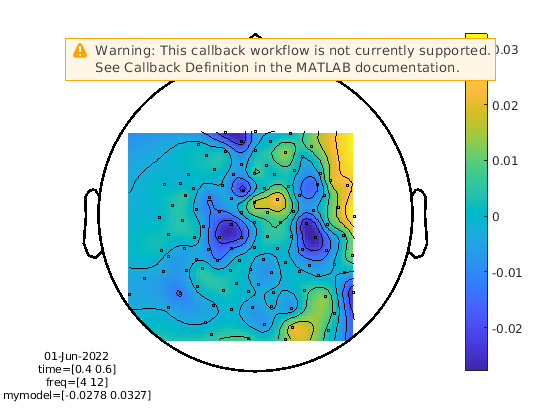

stat.mymodel = stat.model{1}.weights;
cfg = [];
cfg.layout = lay;
cfg.parameter = 'mymodel';
cfg.colorbar = 'yes';
cfg.interplimits = 'electrodes';
ft_topoplotTFR(cfg,stat);